testType = '10sLoadChange';
% testType = 'oscillatingLoadChange';
testType = 'randomLoadChange';

baseAgent = 'v8_RLAgent_SimData';
BaseRLAgentData = load(sprintf('%s_%s.mat', baseAgent, testType)).data;
% v1Data = load(sprintf('v1_BaseRLAgent_SimData_%s.mat', testType)).data;
% v2Data = load(sprintf('v2_RLAgent_SimData_%s.mat', testType)).data;
% v3Data = load('v3RLAgentSimData1sLoadChange.mat').data;
% v4Data = load('v4RLAgentSimData1sLoadChange.mat').data;
% v5Data = load(sprintf('v5_RLAgent_SimData_%s.mat', testType)).data;
v7Data = load(sprintf('v7_RLAgent_SimData_%s.mat', testType)).data;
v8Data = load(sprintf('v8_RLAgent_SimData_%s.mat', testType)).data;
v9Data = load(sprintf('v9_RLAgent_SimData_%s.mat', testType)).data;
v10Data = load(sprintf('v9_RLAgent_SimData_%s.mat', testType)).data;
PIData = load(sprintf('PI_SimData_%s.mat', testType)).data;

plotValues = {
    % {BaseRLAgentData, 'v1'}, 
    % {v2Data, 'v2'}, 
    % {v3Data, 'v3'}, 
    % {v4Data, 'v4'}, 
    % {v5Data, 'v5'}, 
    {v7Data, 'v7'}, 
    {v8Data, 'v8'}, 
    {v9Data, 'v9'},
    {v10Data, 'v10'},
    {PIData, 'PI'}
};
numData = length(plotValues);

plotFrequencyArray = [];
for i = 1:numData
    plotFrequencyArray = [plotFrequencyArray, {plotValues{i}{1}{2}.Values, plotValues{i}{2}}];
end

plotTieLineArray = [];
for i = 1:numData
    plotTieLineArray = [plotFrequencyArray, {plotValues{i}{1}{4}.Values, plotValues{i}{2}}];
end

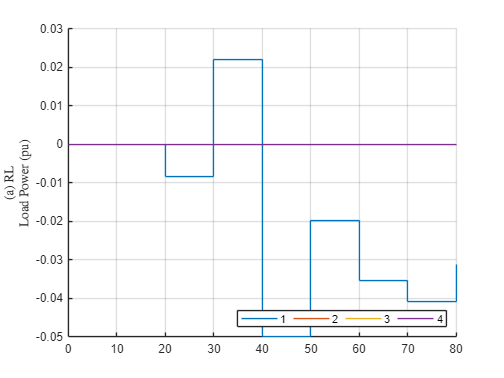


clf
subplot(1,1,1)
hold on
ylabel({'(a) RL', 'Load Power (pu)'}, 'Interpreter', 'latex')
x = BaseRLAgentData{1}.Values;
stairs(x.Time, x.Data(:,1))
stairs(x.Time, x.Data(:,2))
stairs(x.Time, x.Data(:,3))
stairs(x.Time, x.Data(:,4))
legend('1', '2', '3', '4', 'Orientation','horizontal', 'Location','southeast')
grid on
hold off

Frequency

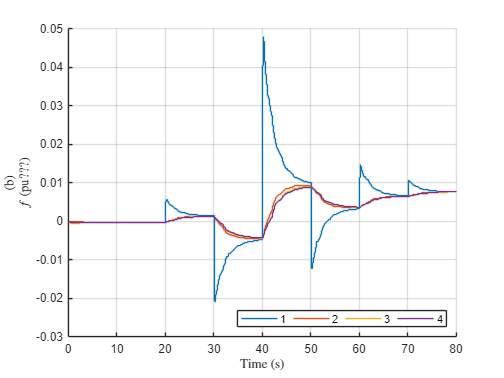



clf
subplot(1,1,1)
hold on
xlabel('Time (s)', 'Interpreter', 'latex')
ylabel({'(b)', '$ f$ (pu???)'}, 'Interpreter', 'latex')
x = BaseRLAgentData{2}.Values;
stairs(x.Time, x.Data(:,1))
stairs(x.Time, x.Data(:,2))
stairs(x.Time, x.Data(:,3))
stairs(x.Time, x.Data(:,4))
legend('1', '2', '3', '4', 'Orientation','horizontal', 'Location','southeast')
grid on
hold off

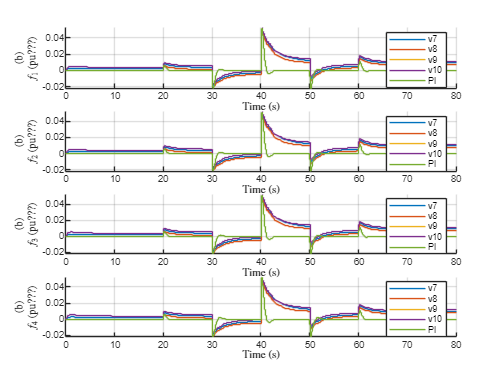


clf
legendEntries = {};
subplot(4,1,1)
hold on
xlabel('Time (s)', 'Interpreter', 'latex')
ylabel({'(b)', '$ f_1$ (pu???)'}, 'Interpreter', 'latex')
x = BaseRLAgentData{2}.Values;
x_PI = PIData{2}.Values;
for i = 1:numData
    stairs(plotFrequencyArray{i*2-1}.Time, plotFrequencyArray{i*2-1}.Data(:,1));
    hold on;  % Keep the previous plot in the figure
    
    % Add an entry to the legend for each plot
    legendEntries{end+1} = [plotFrequencyArray{i*2}];
end
legend(legendEntries);
grid on
hold off

legendEntries = {};
subplot(4,1,2)
hold on
xlabel('Time (s)', 'Interpreter', 'latex')
ylabel({'(b)', '$ f_2$ (pu???)'}, 'Interpreter', 'latex')
for i = 1:numData
    stairs(plotFrequencyArray{i*2-1}.Time, plotFrequencyArray{i*2-1}.Data(:,1));
    hold on;  % Keep the previous plot in the figure
    
    % Add an entry to the legend for each plot
    legendEntries{end+1} = [plotFrequencyArray{i*2}];
end
legend(legendEntries);
grid on
hold off

legendEntries = {};
subplot(4,1,3)
hold on
xlabel('Time (s)', 'Interpreter', 'latex')
ylabel({'(b)', '$ f_3$ (pu???)'}, 'Interpreter', 'latex')
for i = 1:numData
    stairs(plotFrequencyArray{i*2-1}.Time, plotFrequencyArray{i*2-1}.Data(:,1));
    hold on;  % Keep the previous plot in the figure
    
    % Add an entry to the legend for each plot
    legendEntries{end+1} = [plotFrequencyArray{i*2}];
end
legend(legendEntries);
grid on
hold off

legendEntries = {};
subplot(4,1,4)
hold on
xlabel('Time (s)', 'Interpreter', 'latex')
ylabel({'(b)', '$ f_4$ (pu???)'}, 'Interpreter', 'latex')
for i = 1:numData
    stairs(plotFrequencyArray{i*2-1}.Time, plotFrequencyArray{i*2-1}.Data(:,1));
    hold on;  % Keep the previous plot in the figure
    
    % Add an entry to the legend for each plot
    legendEntries{end+1} = [plotFrequencyArray{i*2}];
end
legend(legendEntries);
grid on
hold off

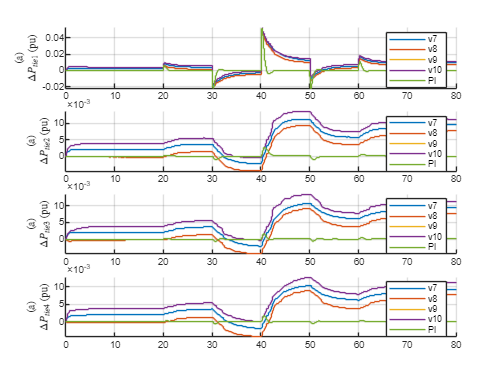

clf
legendEntries = {};
subplot(4,1,1)
hold on
ylabel({'(a)', '$\Delta P_{tie1}$ (pu)'}, 'Interpreter', 'latex')
for i = 1:numData
    stairs(plotTieLineArray{i*2-1}.Time, plotTieLineArray{i*2-1}.Data(:,1));
    legendEntries{end+1} = [plotTieLineArray{i*2}];
end
legend(legendEntries)
grid on
hold off

legendEntries = {};
subplot(4,1,2)
hold on
ylabel({'(a)', '$\Delta P_{tie2}$ (pu)'}, 'Interpreter', 'latex')
for i = 1:numData
    stairs(plotTieLineArray{i*2-1}.Time, plotTieLineArray{i*2-1}.Data(:,2));
    legendEntries{end+1} = [plotTieLineArray{i*2}];
end
legend(legendEntries)
grid on
hold off

legendEntries = {};
subplot(4,1,3)
hold on
ylabel({'(a)', '$\Delta P_{tie3}$ (pu)'}, 'Interpreter', 'latex')
for i = 1:numData
    stairs(plotTieLineArray{i*2-1}.Time, plotTieLineArray{i*2-1}.Data(:,3));
    legendEntries{end+1} = [plotTieLineArray{i*2}];
end
legend(legendEntries)
grid on
hold off

legendEntries = {};
subplot(4,1,4)
hold on
ylabel({'(a)', '$\Delta P_{tie4}$ (pu)'}, 'Interpreter', 'latex')
for i = 1:numData
    stairs(plotTieLineArray{i*2-1}.Time, plotTieLineArray{i*2-1}.Data(:,4));
    legendEntries{end+1} = [plotTieLineArray{i*2}];
end
legend(legendEntries)
grid on
hold off

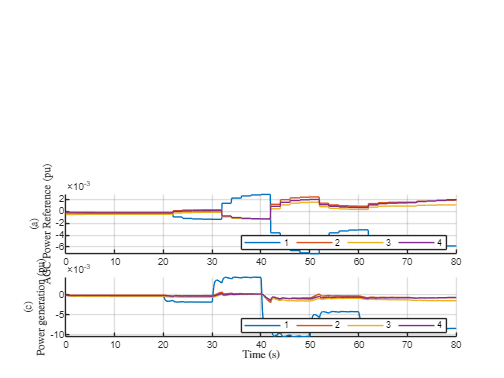

clf
subplot(2,1,1)
hold on
ylabel({'(a)', 'AGC Power Reference (pu)'}, 'Interpreter', 'latex')
x = BaseRLAgentData{9}.Values;
plot(x.Time, x.Data)
% x = RL_run{2}.Values;
% plot(x.Time, x.Data)
legend('1', '2', '3', '4', 'Orientation','horizontal', 'Location','southeast')
grid on
hold off

subplot(2,1,2)
hold on
xlabel('Time (s)', 'Interpreter', 'latex')
ylabel({'(c)', 'Power generation (pu)'}, 'Interpreter', 'latex')
x = BaseRLAgentData{5}.Values;
plot(x.Time, x.Data)
% x = RL_run{4}.Values;
% plot(x.Time, x.Data)
legend('1', '2', '3', '4', 'Orientation','horizontal', 'Location','southeast')
grid on
hold off